clc;
clear;
close all;

load('data_20190604.mat')

mycolor=zeros(3,202);

mycolor(1,:)=[0:0.01:1 zeros(1,101)+1];

mycolor(2,:)=[0:0.01:1 1:-0.01:0];

mycolor(3,:)=[zeros(1,101)+1 1:-0.01:0];

mycolor=mycolor';


t1 = '2019-6-4';
t2 = datenum(t1)+days;
dift1 = abs(dt-datenum(t1));
ind1 = find(dift1 == min(dift1));
dift2 = abs(dt-datenum(t2));
ind2 = find(dift2== min(dift2));

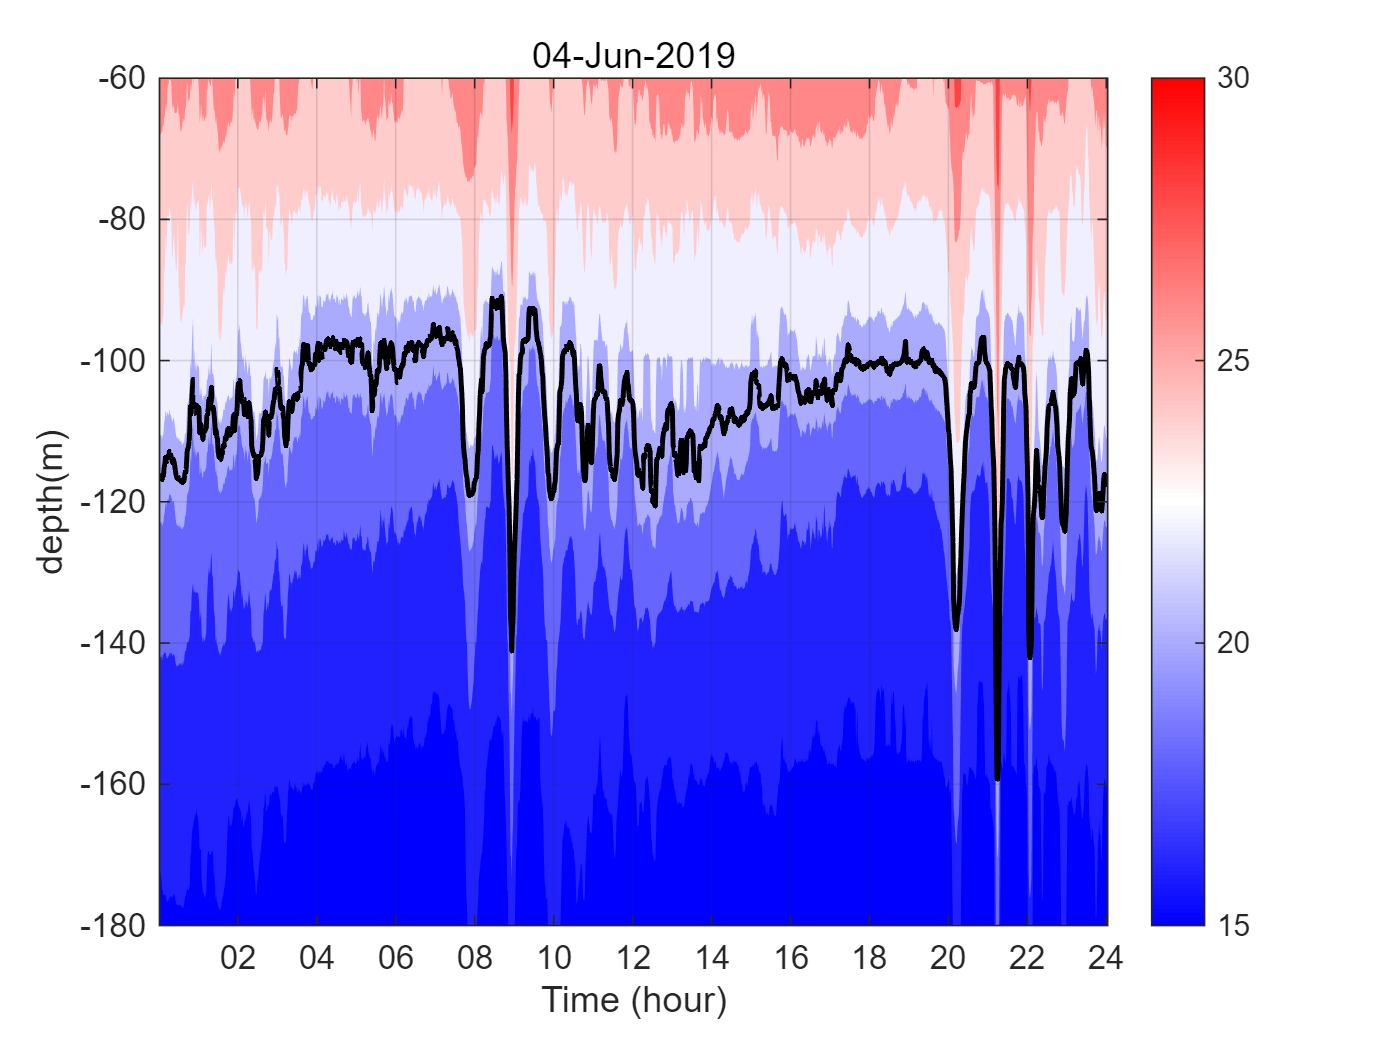


figure
contourf(dt(ind1:ind1+1440),dep,subdata,'linewidth',0.5,'showtext','off','linestyle','none')
shading interp
hold on
[c1,h1] = contour(dt(ind1:ind1+1440),dep,subdata,[21,21],'color','black','linewidth',1.5);
axis tight;
colormap(mycolor);
title(datestr(datenum(t1)),'fontweight','normal')
datess = datestr(datenum(t1));
ylabel('depth(m)','FontName','Arial')
h = colorbar;
caxis([15,30])
ylim([-180,-60])
set(gca,'xtick',[])
grid on
box on

xlabel('Time (hour)','FontName','Arial')
set(gca,'xtick',dt(ind2-1440):1/1440*120:dt(ind2))
set(gca,'xticklabels', {'00','02','04','06','08','10','12','14','16','18','20','22','24',},'fontName','Arial' )

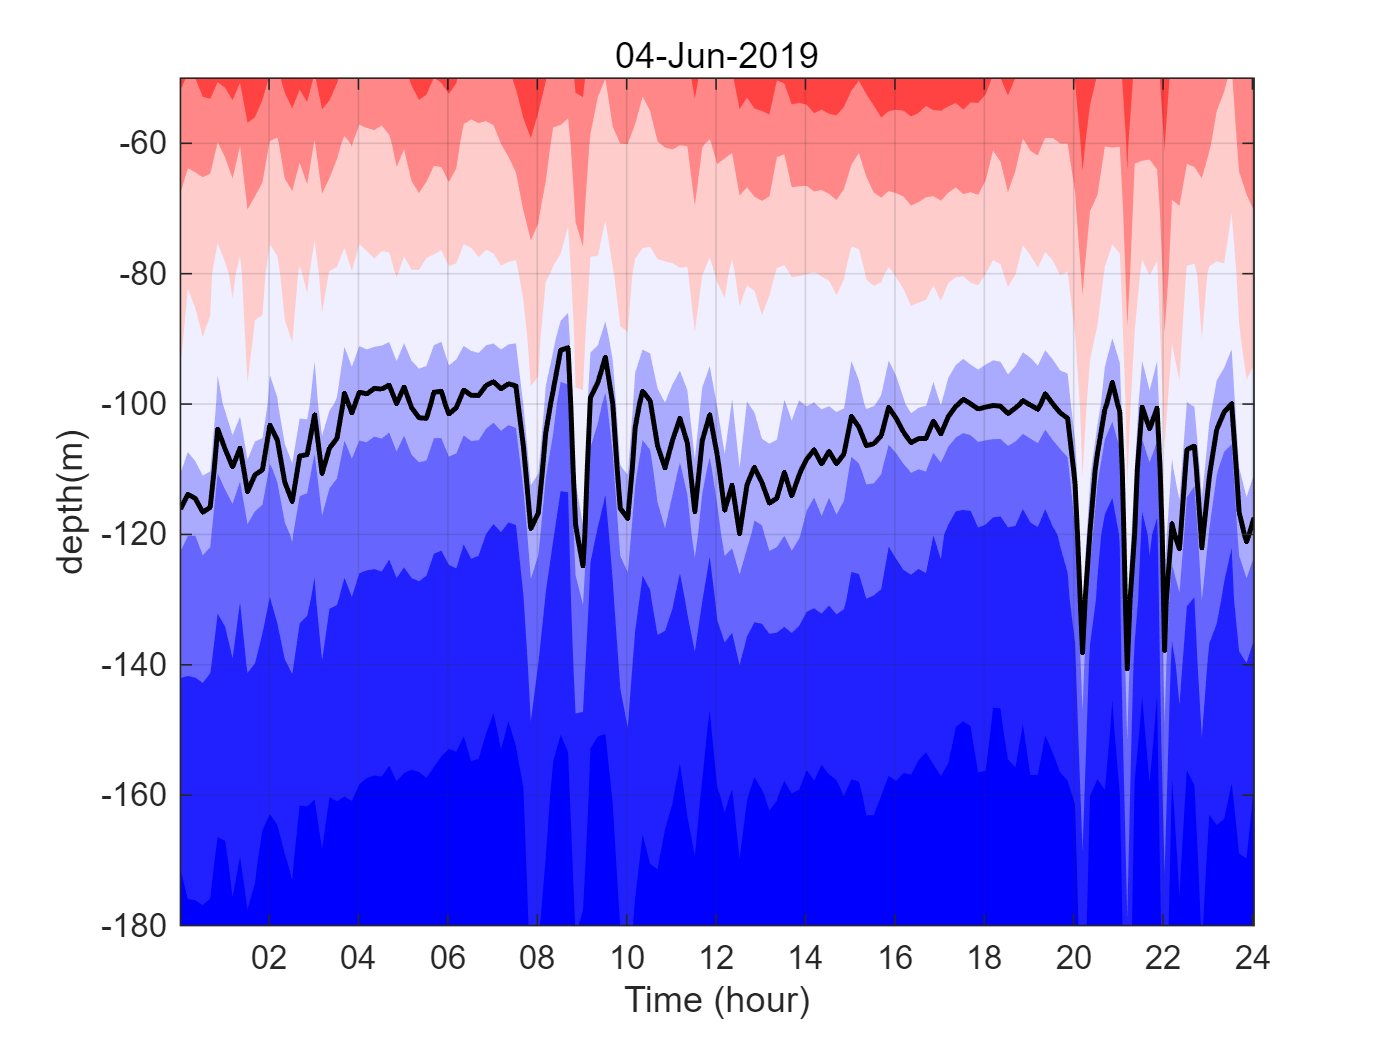


k=1;
subdata2 = subdata(:,1:10:end);
figure
contourf(dt(ind1+(k-1)*1440:10:ind1+(k)*1440),dep,subdata2,'linewidth',0.5,'showtext','off','linestyle','none')
shading interp
hold on
[c2,h1] = contour(dt(ind1+(k-1)*1440:10:ind1+(k)*1440),dep,subdata2,[21,21],'color','black','linewidth',1.5);
axis tight;
colormap(mycolor);
title(datestr(datenum(t1)),'fontweight','normal')
datess = datestr(datenum(t1));
ylabel('depth(m)','FontName','Arial')
caxis([15,30])
ylim([-180,-50])
set(gca,'xtick',[])
grid on
box on
xlabel('Time (hour)','FontName','Arial')
set(gca,'xtick',dt(ind2-1440):1/1440*120:dt(ind2))
set(gca,'xticklabels', {'00','02','04','06','08','10','12','14','16','18','20','22','24',},'fontName','Arial' )

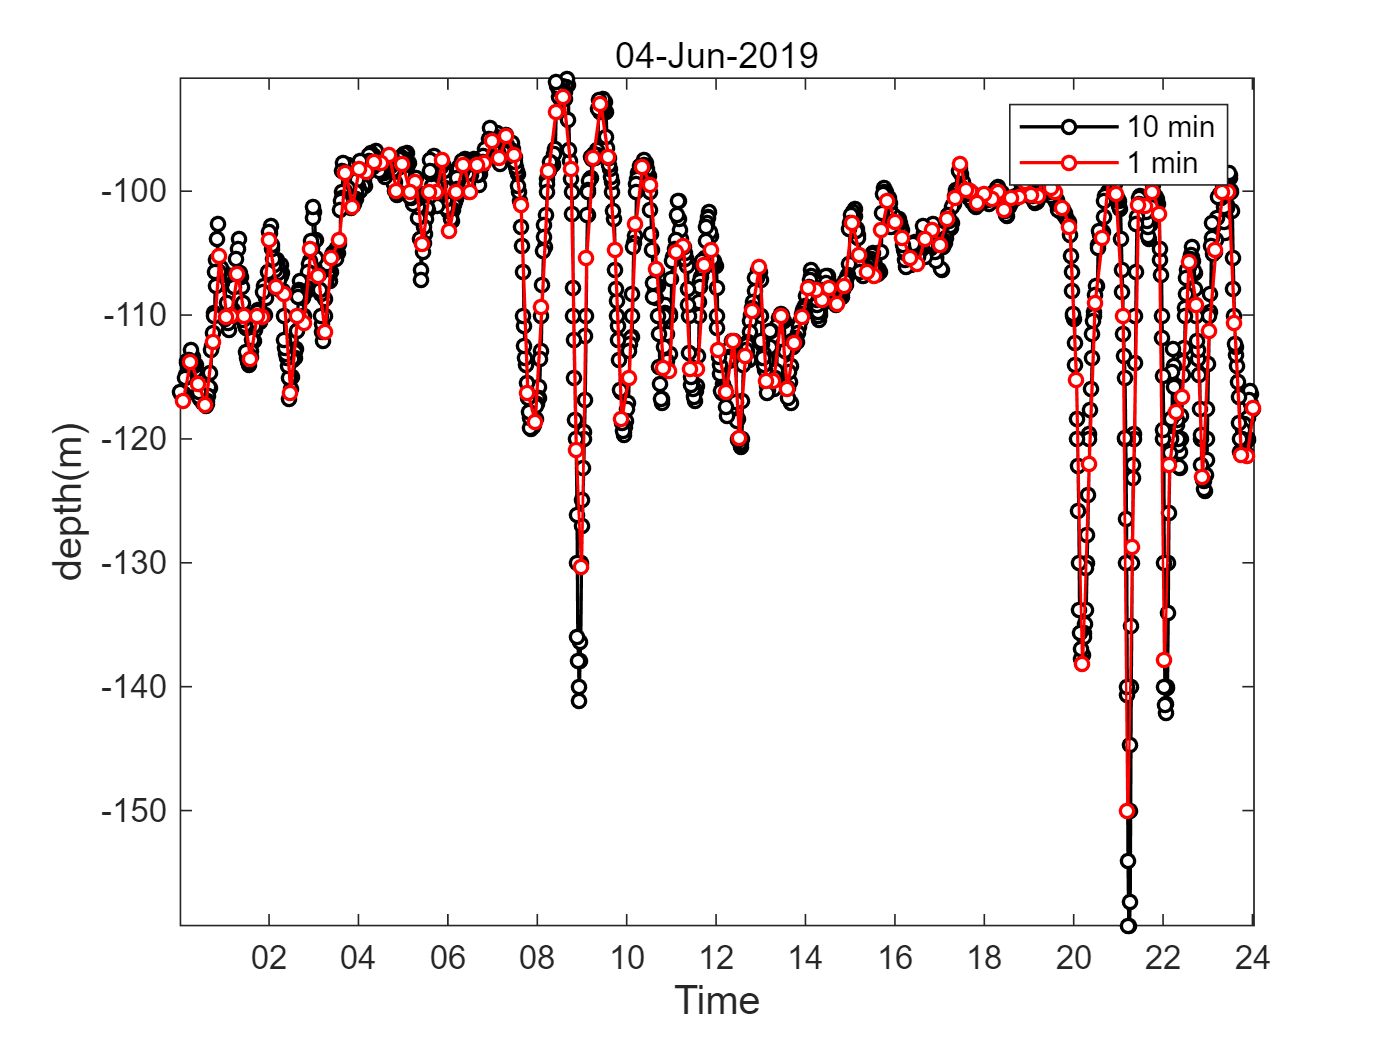

s=contourdata(c1);
xx = s(1).xdata;
yy = s(1).ydata;
figure
plot(xx,yy,'k-o','linewidth',1,"MarkerSize",4,"MarkerFaceColor","auto");
hold on
plot(xx(1:10:end),yy(1:10:end),'r-o','linewidth',1,"MarkerSize",4,"MarkerFaceColor","auto");
ylim([-140,-60])
xlabel('Time','FontName','Arial','fontsize',12)
ylabel('depth(m)','FontName','Arial','fontsize',12)
set(gca,'xtick',dt(ind2-1440):1/1440*120:dt(ind2))
set(gca,'xticklabels', {'00','02','04','06','08','10','12','14','16','18','20','22','24',},'fontName','Arial' )
title(datestr(datenum(t1)),'fontweight','normal')
axis tight
legend('10 min','1 min')